clf
clear
clc

A = [-4,2,1,0,0;1,-4,1,1,0;2,1,-4,1,2;0,1,1,-4,1;0,0,1,2,-4];
b = [-4;11;-16;11;-4];
x0 = [0;0;0;0;0];

L = -tril(A,-1);
U = triu(A,1);
D = diag(diag(A));
N = 100;
T = inv(D)*(L+U);
c = inv(D)*b;
errlimit = 1e-6;

for i = 1:N
    x = T*x0 + c;
    Error = norm(x - x0);
    if Error <= errlimit
        disp("this is converged at: "+i);
        disp(x);
        break
    else
        x0 = x;
    end
end

this is converged at: 58


    1.3529
   -2.8235
    4.2353
   -2.5882
    0.7647



e1 = 24;
e2 = 10;
e3 = 5;

ev1 = [1;1;0];
ev2 = [1;-1;0];
ev3 = [0;0;1];

V = [ev1 ev2 ev3];
D = diag([e1 e2 e3]);

A = V*D*inv(V)

A =     17     7     0
     7    17     0
     0     0     5


A5 = V*D^5*inv(V)

A5 =      4031312     3931312           0
     3931312     4031312           0
           0           0        3125


clc 
clf
clear

A = randi([1,10],7,9);
s = svd(A);

fnorm = norm(A,'fro')

fnorm = 44.7884

nunorm = norm(s,1)

nunorm = 84.9080

specnorm = s(1)

specnorm = 39.3434

clc
clear

u = [2;9;-1];
v = [3;0;8];
S = [9,2,2;2,9,2;2,2,9];

eig(S)

ans =     7.0000
    7.0000
   13.0000



snormu = u'*S*u

snormu = 802

snormv = v'*S*v

snormv = 753


L2u = norm(u,2)

L2u = 9.2736

L2v = norm(v,2)

L2v = 8.5440


fnorm = norm(S,'fro')

fnorm = 16.3401

clf
clear
clc

A = [2,1,-1;1,2,-1;-1,-1,4];
b = [1;2;9];
x0 = [0;0;0];
xa = x0;

for i = 1:10
    g = A*x0 - b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errlimit = norm(A*xn - b,2);
    if errlimit <= 0.001
        break
    end
end
xa

xa =          0    0.3028    0.9872    0.9875    1.0853    1.0515    1.0576    1.0311    1.0283    1.0146    1.0128
         0    0.6056    1.4798    1.6356    1.8319    1.8810    1.9388    1.9541    1.9754    1.9805    1.9894
         0    2.7254    2.4551    2.9600    2.8993    3.0039    2.9787    3.0074    2.9935    3.0041    2.9974


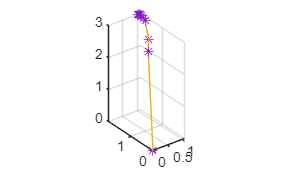


plot3(xa(1,:),xa(2,:),xa(3,:));
hold on
plot3(xa(1,:),xa(2,:),xa(3,:),'*');
hold on
grid on
axis equal

clf
clear
clc

% x1 = -4:.25:3;
% x2 = -4:.25:7;
% [X1,X2] = meshgrid(x1,x2);

A = [8,0;0,6];
b = [16;36];
x0 = [0;0];
xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = (g'*g)/(g'*(A*g));
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    err = norm(A*xn - b,2);
    if err <= 0.001
        break
    end
end

plot(xa(1,:),xa(2,:))
hold on
plot(xa(1,:),xa(2,:),'*')
grid on
axis equal

A = [8,2,1;2,7,2;1,2,5];
n = size(A,1);
D = zeros(n);

D(:,1) = [1;0;0];

for k = 2:n
    v = zeros(n,1);
    v(k) = 1;
    for j = 1:k-1
        beta = (D(:,j)'*A*v)/(D(:,j)'*A*D(:,j))
        v = v - beta*D(:,j);
    end
    D(:,k) = v;
end

beta = 0.2500

beta = 0.1250

beta = 0.2692

D

D =     1.0000   -0.2500   -0.0577
         0    1.0000   -0.2692
         0         0    1.0000


A = [8,2,1;2,7,2;1,2,5];
n = size(A,1);
D = zeros(n);

D(:,1) = [1;0;0];

for k = 2:n
    v = zeros(n,1)
    v(k) = 1;

    for j = 1:k-1
        beta = (D(:,j)'*A*v)/(D(:,j)'*A*D(:,j))
        v = v - beta*D(:,j);
    end
    D(:,k) = v;
end

v =      0
     0
     0


beta = 0.2500

v =      0
     0
     0


beta = 0.1250

beta = 0.2692

D

D =     1.0000   -0.2500   -0.0577
         0    1.0000   -0.2692
         0         0    1.0000


A = [11,2,1;2,4,-1;1,-1,6];
b = [12;1;7];
x0 = [0;0;0];

r0 = b-A*x0;
d0 = r0;

for i = 1:100
    Ad = A*d0;
    alpha = (r0'*r0)/(d0'*Ad);
    x = x0 + alpha*d0;
    r = r0 - alpha*Ad;
    err = norm(r,2)
    if (err <= 1e-10)
        break
    end
    beta = (r'*r)/(r0'*r0);
    d0 = r + beta*d0;
    r0 = r;
    x0 = x;
end

err = 2.5394

err = 0.1334

err = 8.5227e-16

x0

x0 =     1.0117
   -0.0405
    0.9848


X=[2,4,5,6,8,11];
Y=[18,12,10,8,7,5];

C = cov(X,Y)

C =    10.0000  -13.4000
  -13.4000   21.2000


R = C(1,2)/(sqrt(C(1,1)).*sqrt(C(2,2)));

scatter(X,Y,'*')
hold on
grid on

p = polyfit(X,Y,1)

p =    -1.3400   18.0400


m = p(1)

m = -1.3400

c = p(2)

c = 18.0400

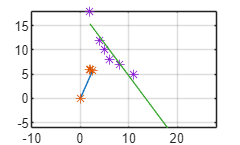


xfit = linspace(min(X),max(Y),100);
yfit = m*xfit+c;

plot(xfit,yfit)